# Making Charts

## Line Chart

macPCSales = readtable("MacPCSales.csv")

macPCSales = 20x4 table
    Year    Mac      PC      MacShare
    ____    ____    _____    ________

    2004     4.1    229.5      1.8   
    2005     5.7    240.1      2.4   
    2006     6.2    254.4      2.4   
    2007     7.6    275.5      2.7   
    2008     9.1    285.5      3.2   
    2009     9.4    260.8      3.6   
    2010    13.8    306.3      4.5   
    2011      17    290.4      5.8   
    2012    15.4    270.6      5.7   
    2013    16.3    257.5      6.3   
    2014    18.9    289.6      6.5   
    2015    20.1    260.4      7.7   
    2016    20.6    260.9      7.9   
    2017    19.6    256.2      7.6   
    2018    19.5    253.1      7.7   
    2019    18.9    254.3      7.4   


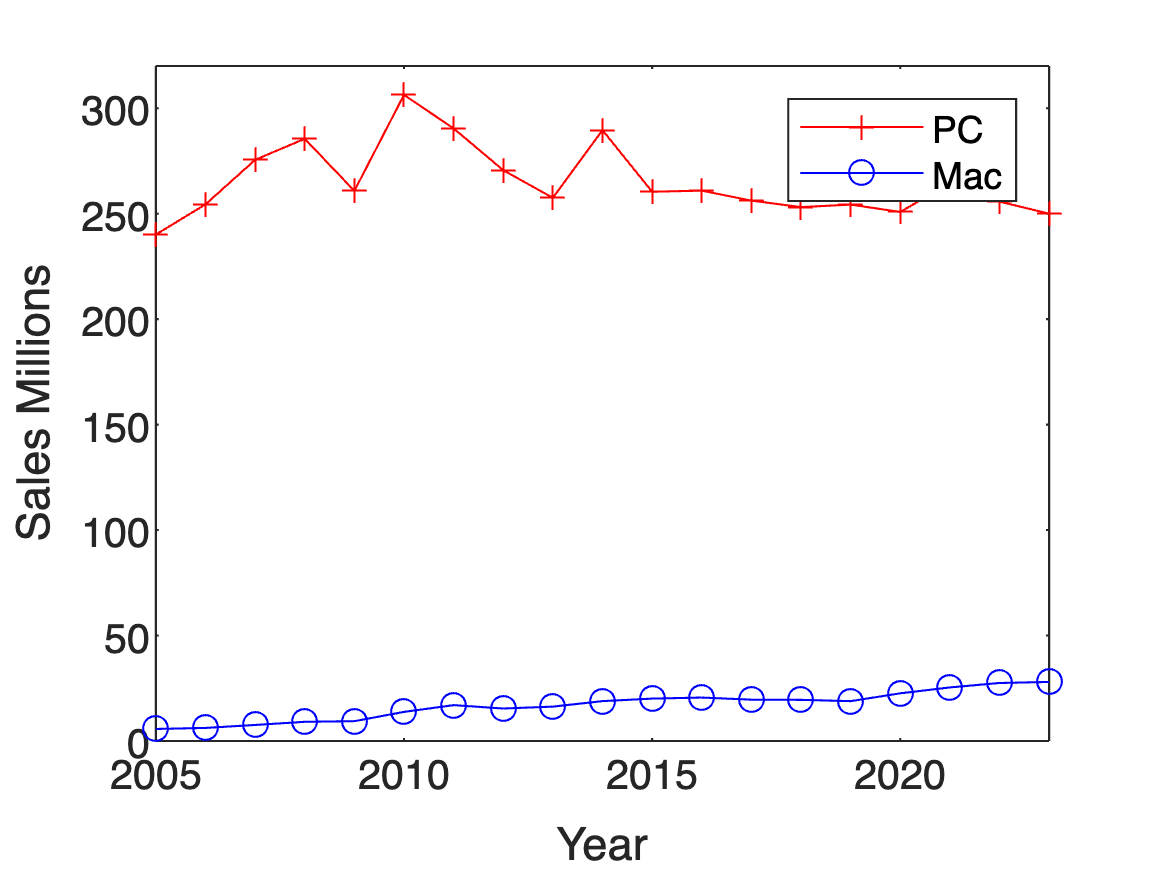

plot(macPCSales.Year, macPCSales.PC,"r-+")
hold on;
plot(macPCSales.Year,macPCSales.Mac,"b-o")
xlabel("Year")
ylabel("Sales Millions")
xlim([2005 2023])
ylim([0 320])
legend(["PC" "Mac"])
hold off

## Bar chart

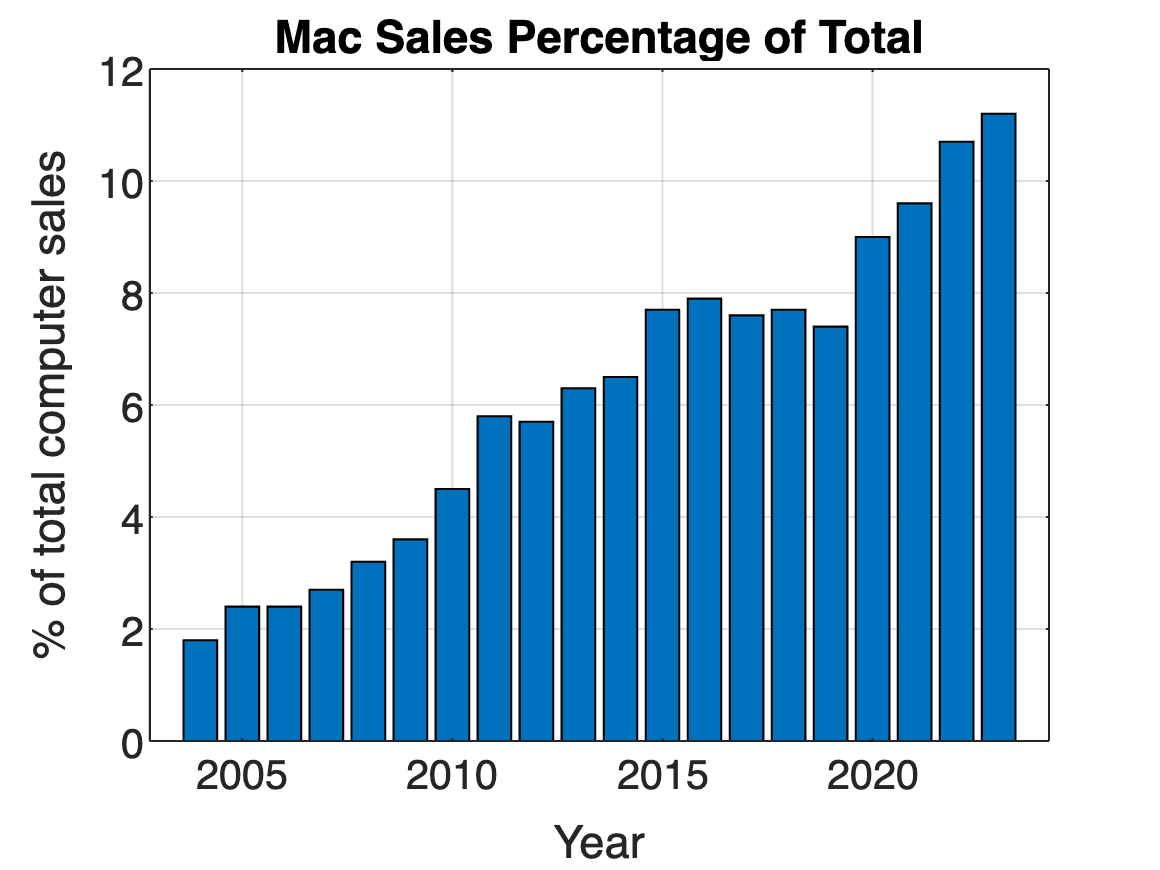

bar(macPCSales.Year, macPCSales.MacShare)
title("Mac Sales Percentage of Total")
xlabel("Year")
ylabel("% of total computer sales")
grid

## Error Bars

labdata = readtable("Physics Lab Data.csv");

labdata.pred = (labdata.PullingMass * 9.8) ./ (labdata.CartMass + labdata.PullingMass);
labdata.err = abs(labdata.Acceleration - labdata.pred)

labdata = 4x5 table
    CartMass    PullingMass    Acceleration    pred    err 
    ________    ___________    ____________    ____    ____

      0.43         0.06            1.14        1.2     0.06
      0.37         0.12            2.34        2.4     0.06
      0.31         0.18            3.76        3.6     0.16
      0.25         0.24            4.83        4.8     0.03


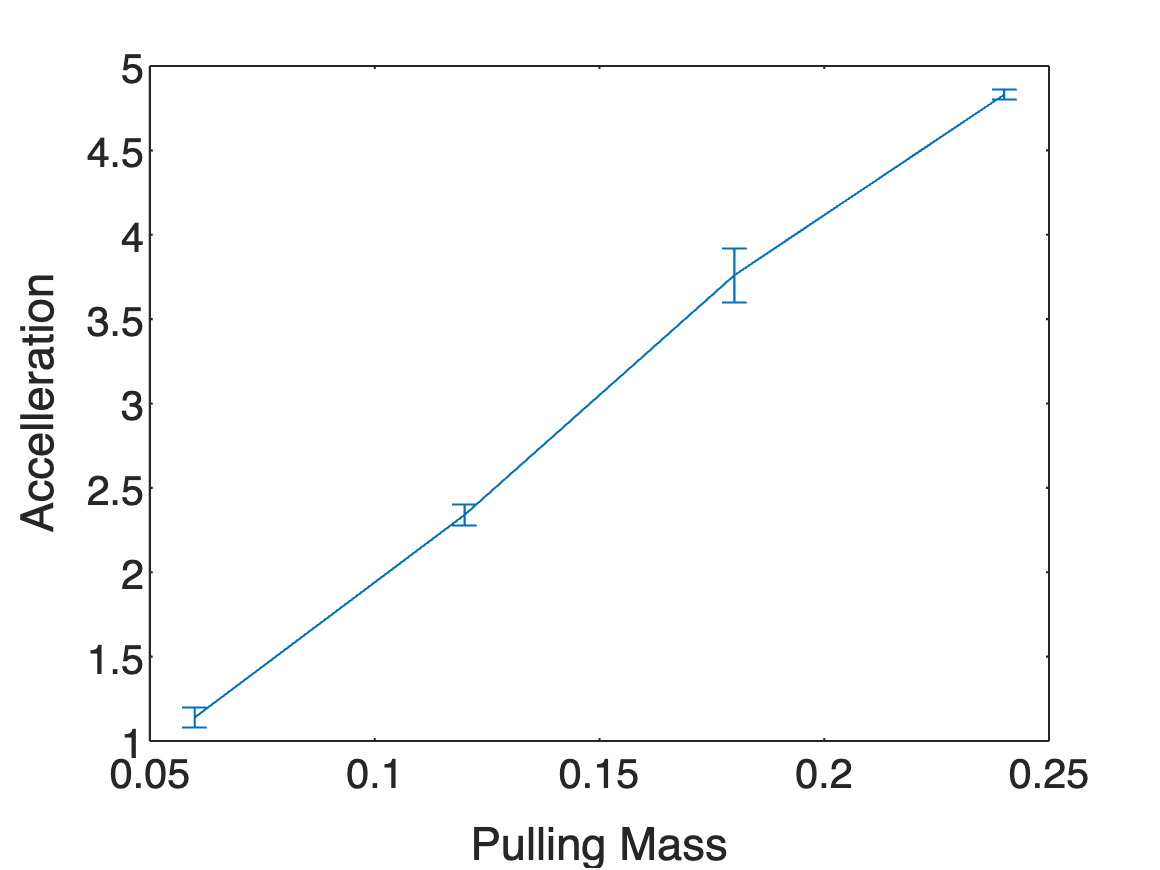

errorbar(labdata.PullingMass, labdata.Acceleration, labdata.err)
xlabel("Pulling Mass")
ylabel("Accelleration")